% Experiment on the Cascaded watertanks benchmark
%
% References
% ---------
%
% A Tensor Network Kalman filter with an application in recursive MIMO Volterra system identification
% 2016, Kim Batselier, Zhongming Chen, Ngai Wong
% 

clear all
close all
clc

%for reproducibility
rng(1);

load('dataBenchmark')


% uEst=smoothdata(uEst,'gaussian',2);
% yEst=smoothdata(yEst,'gaussian',2);

% figure
% hold on
% plot(uEst)
% plot(yEst)
% hold off
% for i =1:7
% uEst = [uEst ;(uEst+0.0*rand(size(uEst)))];
% yEst = [yEst ;(yEst+0.5*rand(size(yEst)))];
% end
% 
% yEst(yEst>10)=10;
% plot(uVal)
% plot(yVal)

% autocorr(uEst,1000)
% autocorr(yEst,1000)

% parcorr(uEst,1000)
% parcorr(yEst,1000)

Preprocessing Data

tic

% Normalize the input and output training data to [0 1]
input = uEst/7;
output = yEst/10-0.1;

% plot(input)
% plot(output)
% 
% histogram(input)
% histogram(output)

% Normalize the input and output test data to [0 1]
tinput = uVal/7 ;
toutput = yVal/10-0.1;

% Choose the lags for the input and output
inlags=[1 2];
outlags=[0 1 2 4 8 12 16];

ending = 1024-outlags(end)-1;

% generate features using input lags
for l = 1:length(inlags)
u(:,l) = input(end-inlags(l)-ending:end-inlags(l));
uv(:,l) = tinput(end-inlags(l)-ending:end-inlags(l));
end
% generate features using output lags
for l = 1:length(outlags)
y(:,l) = output(end-outlags(l)-ending:end-outlags(l));
yv(:,l) = toutput(end-outlags(l)-ending:end-outlags(l));
end



Split test and training set

% Features are lagged inputs and outputs
featurez = [y(:,end:-1:2)  u];
% Target is output with zero lag
zeta = y(:,1);

tfeaturez = [yv(:,end:-1:2)  uv];
yt = yv(:,1);



Construct B-spline basis vectors


[N, d]=size(featurez); % Number of samples and features

n = 3;                  %Degree B-spline
m = 1;                  %Number of knot intervals
In = n+m;               %Number of B-splines

% Construct the basis vectors from the features
un = basisvectors(featurez,n,m);




Initialize tensor train

% Choose TT-ranks
maxrank = 5;

r = (min(min(In.^[0:d],In.^[d:-1:0]),maxrank));


% Initialize Tensor Train and Vp and Vm
[TN,Vm,Vp] = initTT(un,r,d);


Show storage compression ratio


Pcount = (In)^d;                    %Original tensor size
dof = sum(prod(TN.sz,2));           %TT storage size.
disp(['Compression: ' num2str(dof/Pcount)])  %compression ratio

Compression: 0.0090332


Optimize TT cores

% rez = [];

lambda=2*10^-4;

difforder=2;
MAXITR = 12;

% nselect = floor(logspace(log10(dof/N),0,MAXITR)*0.5*N);


% MAXITR = d;
nselect = ones([1,MAXITR])*N;
% plot(nselect)

[TN,Vm,Vp,res1,res2] = optimTT(TN,Vm,Vp,un,zeta,MAXITR,nselect,lambda,difforder);


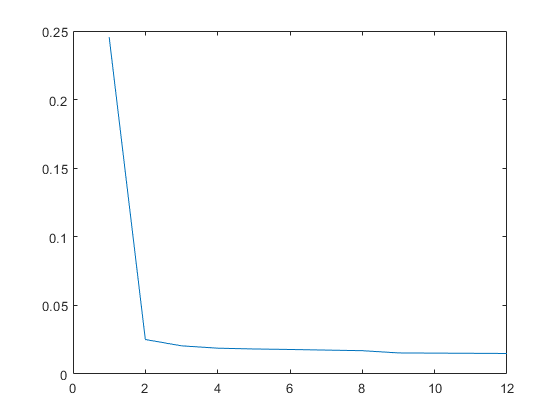


plot(res1)

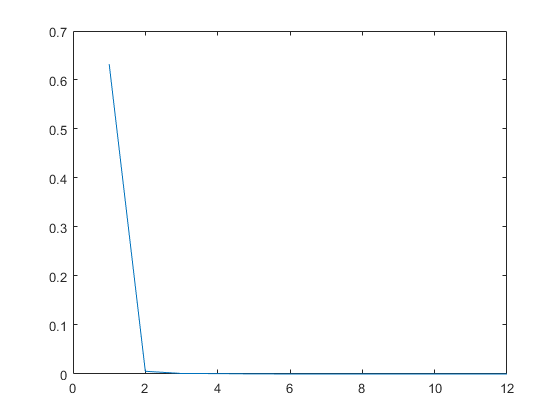

plot(res2)

Evaluate Train data


% yhattrain  = evalspline(TN,featurez,n,m);
% 
% figure;
% hold on
% plot(zeta)
% plot(yhattrain)
% hold off
% axis([0 inf -inf inf]);
% 
% erboiz = (yhattrain-zeta);
% VAF = 1-var(erboiz)/var(zeta)
% MSE = immse(yhattrain,zeta)



Evaluate Test data


yhat = evalspline(TN,tfeaturez,n,m);
erboi = (yhat-yt);
% histogram((erboi)');
VAF = 1-var(erboi)/var(yt)

VAF = 0.9995

MSE = immse(10*yhat,10*yt)

MSE = 0.0021



RMSE1 = sqrt(immse(10*yhat,10*yt))

RMSE1 = 0.0461

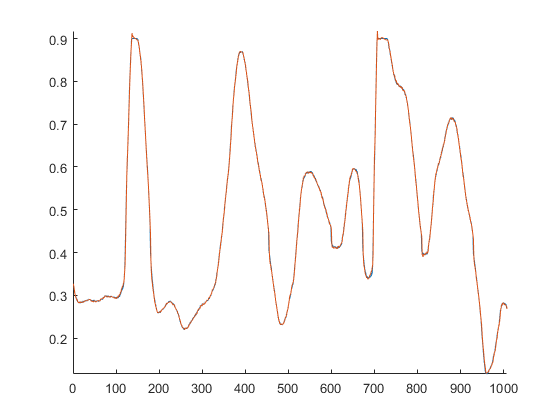


figure
hold on
plot(yt)
plot(yhat)
hold off
axis([0 inf -inf inf])

 Visualize errors

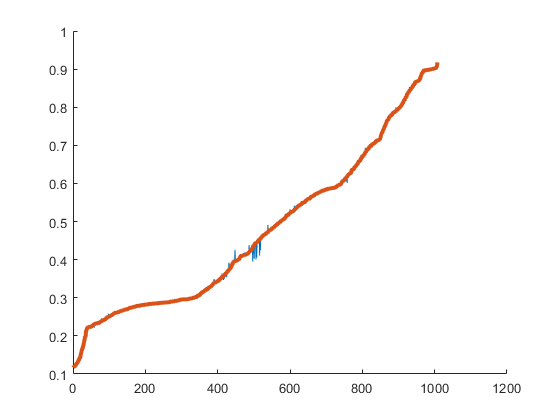

[sortout,Iss]=sort(yhat);
figure
hold on
plot(yt(Iss))
plot(sortout,'Linewidth',3)
hold off

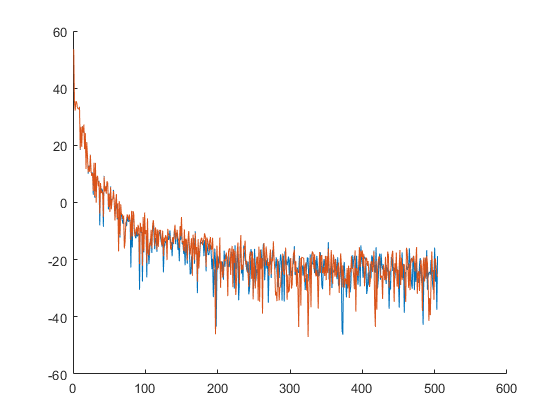


FY = mag2db(abs(fft(yhat)));
FZ = mag2db(abs(fft(yt)));

figure;
hold on
plot(FZ(1:floor(end/2)))
plot(FY(1:floor(end/2)))
hold off

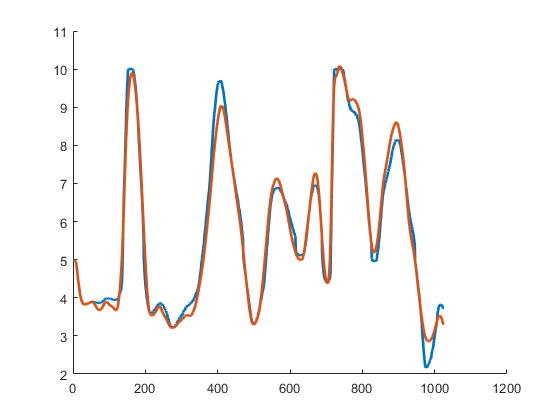


siminput = tinput;
simoutput = toutput;
numz = numel(outlags);
beginz = outlags(end)+1;
for j = beginz:1024
simfeaturez = [simoutput(j-outlags(end:-1:2))' siminput(j-inlags(1:end))'];
simfeaturez(simfeaturez<0)=0;
simfeaturez(simfeaturez>1)=1;
simoutput(j) = evalspline(TN,simfeaturez,n,m);
end

figure
hold on
plot(10*toutput+1,'linewidth',2)
plot(10*simoutput+1,'linewidth',2)
hold off


RMSE = sqrt(immse(10*toutput(beginz:end),10*simoutput(beginz:end)))

RMSE = 0.2991

toc

Elapsed time is 2.031633 seconds.


% surf(RMSE)
% xlabel('lambda * 10^-2')
% ylabel('RMSE')
% 
% zlabel('RMSE')
% plot(RMSE)
% xlabel('lambda * 10^-2')
% ylabel('RMSE')
% 
% bar(1:5,RMSE(6:10))

